clearvars;  
%measurement settings
format shortG
%magnet parameters
3/16

ans =        0.1875


1/8

ans =         0.125


diameter = 3/16*25.4 %mm

diameter =        4.7625


height = 1/8*25.4 %mm

height =         3.175


Br_max = 14800*0.1; %mT
mu_0 =  4*pi*10^-7*1000*1000; % mT mm/A^2
sensorheight = 35; %mm
%want M in A/m
M=Br_max;
B_t = pi*(diameter/2)^2*height*Br_max/(4*pi);
sensor_separation = 4.5; %mm
num_sensors=16;

% Parameters
y_values = -2:1:3; % Increment y from -2 to 2
x_values = -2:1:3; % Increment x from -2 to 2
z_values = 0;  % z values for 0 and 2

% Initialize the matrix to store coordinates
location = zeros(length(y_values) * length(x_values) * length(z_values), 3);

% Loop to generate coordinates
index = 1;
for y = y_values
    for x = x_values
        location(index, :) = [x, y, 0];
        index = index + 1;
    end
end


location = location(:, [2, 1, 3]).*1;
location

location =     -2    -2     0
    -2    -1     0
    -2     0     0
    -2     1     0
    -2     2     0
    -2     3     0
    -1    -2     0
    -1    -1     0
    -1     0     0
    -1     1     0


% Specify the common part of the file name
file_prefix = 'C:\Users\Brandon Nguyen\Documents\Github\magnetic-sensor-data\MLX02072024_D32N52_test4\sensor_';
file_suffix = '_averages.csv';

% Loop to create variables sen1, sen2, ..., sen16
for sensor_num = 1:num_sensors
    % Construct the file name for the current sensor
    file_name = [file_prefix, num2str(sensor_num), file_suffix];

    try
        % Read the CSV file using readtable
        data_table = readtable(file_name, 'Delimiter', ',', 'VariableNamingRule', 'preserve');

        % Extract data matrix
        data_matrix = cell2mat(cellfun(@eval, data_table{:, :}, 'UniformOutput', false));

        % Create a variable name for the data
        variable_name = ['sen', num2str(sensor_num)];

        % Assign the data to a variable with a dynamically generated name
        eval([variable_name, ' = data_matrix;']);
    catch
        % Handle any errors (you can add specific error handling if needed)
        fprintf('Error reading data for sensor %d\n', sensor_num);
    end
end

% Number of sensors
num_sensors = 16;

sensor_actual = [
    0, 0, 0;
    -4.5, 0, 0;
    -9.0, 0, 0;
    -13.5, 0, 0;
    0, 4.5, 0;
    -4.5, 4.5, 0;
    -9.0, 4.5, 0;
    -13.5, 4.5, 0;
    0, 9.0, 0;
    -4.5, 9.0, 0;
    -9.0, 9.0, 0;
    -13.5, 9.0, 0;
    0, 13.5, 0;
    -4.5, 13.5, 0;
    -9.0, 13.5, 0;
    -13.5, 13.5, 0
];

sensor_actual = sensor_actual + [13.5/2 -13.5/2 0];

% Adjust the location for the magnet
loc = location + [0, 0, 17];

01312024

calculate magnetic field strengths of other magnets - find combination with largets magnetic field strength 

Redo measurements closer to sensor (maybe try n52 right away)

Use smallest magnet "reasonably" detecable at 2 cm. (just measure all of them at 2cm)

    Use strongest magnet, play with z-distance, decreae

Try fitting with center 4 sensors only

% Create a cell array to store all rows
all_sen = cell(length(data_matrix), 16);

% Access each row of each matrix and store in the cell array
for row = 1:length(data_matrix)
    for sensor = 1:16
        sens = eval(['sen', num2str(sensor)]);
        all_sen{row, sensor} = sens(row,:);
    end
end

all_sen

all_sen = 36×16 cell array
    {[-0.99475 0.27263 0.92928]}    {[  -0.88165 0.43875 1.82]}    {[   -0.21621 0.57122 2.4]}    {[ 0.6903 0.52136 2.1318]}    {[  -1.021 -0.1746 0.96541]}    {[ -0.93276 -0.33681 1.831]}    {[-0.22307 -0.42013 2.5915]}    {[0.72159 -0.39686 2.2219]}    {[-0.84536 -0.54645 0.72445]}    {[-0.71175 -0.86272 1.3483]}    {[ -0.14737 -1.0744 1.7639]}    {[ 0.53572 -0.95399 1.532]}    {[-0.52697 -0.57888 0.36782]}    {[-0.43186 -0.85749 0.68525]}    {[ -0.08958 -1.0314 0.86367]}    {[0.31491 -0.96647 0.76092]}
    {[-0.95313 0.35787 0.87938]}    {[-0.83752 0.57682 1.7092]}    {[-0.20248 0.74945 2.2467]}    {[0.66656 0.67903 1.9953]}    {[-1.0364 -0.07479 0.98956]}    {[ -0.9502 -0.16701 1.8855]}    {[-0.22493 -0.19389 2.6675]}    {[ 0.74461 -0.19983 2.286]}    {[ -0.90543 -0.49627 0.8009]}    {[-0.77466 -0.79419 1.5007]}    {[-0.16262 -0.99811 1.9784]}    {[ 0.5874 -0.88384 1.7173]}    {[-0.58563 -0.58557 0.43923]}    {[-0.49093 -0.88423 0.80961]}    {[  -0.10284 

multipreds = [];
multifvals = [];
for t = 1:length(sen1)
        tt = [all_sen{t,:}];
        costfun = @(v)mmcost(v, B_t, sensor_actual, tt, 1, 16);
        nonlcon = @con;

        x0 = [0, 0, 0, 5, 5, 55];
        A = [];
        b = [];
        Aeq = [];
        beq = [];
        lb = [-1, -1, -1, -100, -100, 0];
        ub = [1, 1, 1, 100, 100, 100];
        [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
        multipreds = [multipreds; locs];
        multifvals = [multifvals; fval];
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

multiang = multipreds(:,1:3)

multiang =     -0.057183    0.0033717      0.91319
    -0.062446    0.0080981      0.91077
     -0.05993     0.011525      0.90732
    -0.058684     0.013944      0.90581
    -0.055529     0.016506      0.90365
    -0.054997     0.017542      0.90439
    -0.053202    -0.001553      0.91207
    -0.057349    0.0016694      0.91287
    -0.055802    0.0083494      0.91091
    -0.055603      0.01193      0.91104


multiloc = multipreds(:,4:6)

multiloc =       -3.5576       -4.058        16.68
      -3.5766      -3.0298       16.658
      -3.5468      -1.9975       16.636
      -3.5197     -0.97545       16.622
       -3.483     0.046686       16.606
      -3.4681       1.0613       16.602
      -2.5325      -4.0916       16.692
      -2.5474      -3.0742       16.696
      -2.5217      -2.0247       16.684
      -2.5101     -0.99228       16.684


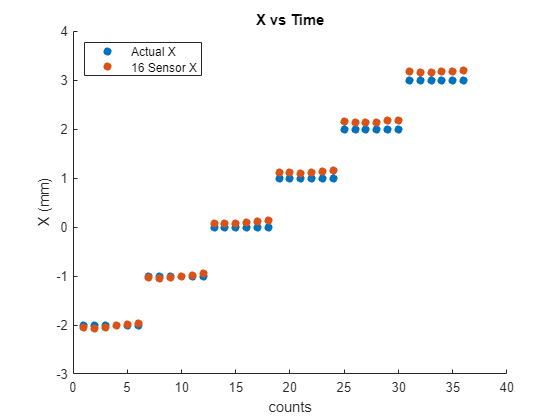

scatter(1:length(multiloc),loc(:,1), 'filled')
hold on;
scatter(1:length(multiloc), multiloc(:,1)+1.5, 'filled')
title('X vs Time')
xlabel('counts')
ylabel('X (mm)')
%ylim([-3,4])
legend('Actual X','16 Sensor X', Location='northwest')
hold off;

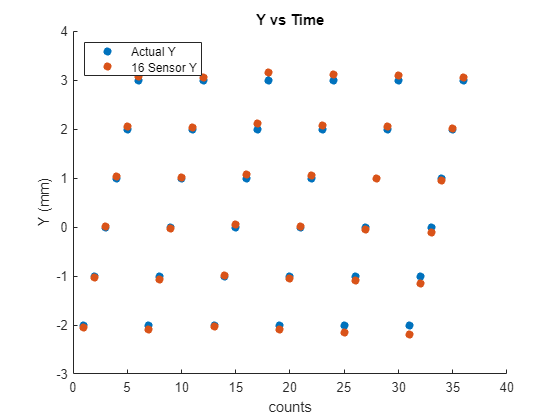

scatter(1:length(multiloc),loc(:,2), 'filled')
hold on;
scatter(1:length(multiloc), multiloc(:,2)+2, 'filled')
title('Y vs Time')
xlabel('counts')
ylabel('Y (mm)')
%lim([-3,7])
legend('Actual Y','16 Sensor Y', Location='northwest')
hold off;

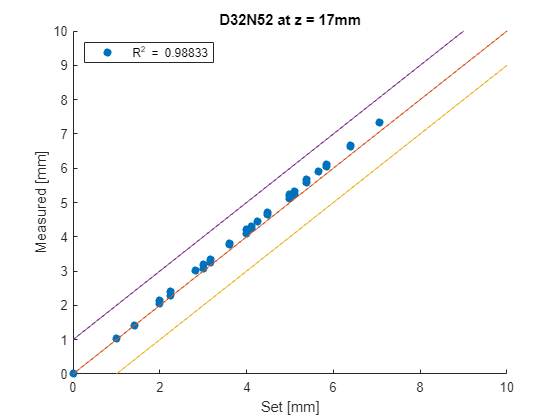

r0 = [multiloc(1,1) multiloc(1,2) multiloc(1,3)];
testx =sqrt(sum((multiloc-r0).^2, 2));
zi = [5.000
5.099
5.385
5.831
6.403
7.071
5.099
5.196
5.477
5.916
6.481
7.141
5.385
5.477
5.745
6.164
6.708
7.348
5.831
5.916
6.164
6.557
7.071
7.681
6.403
6.481
6.708
7.071
7.550
8.124
7.071
7.141
7.348
7.681
8.124
8.660
];

r02 = [location(1,1) location(1,2) location(1,3)];
zi2 = sqrt(sum((location-r02).^2, 2));

scatter(zi2, testx, 'filled')
hold on;
plot(0:10, 0:10)
plot(0:10, -1:9)
plot(0:10, 1:11)
ylim([0 10])
xlabel("Set [mm]")
ylabel('Measured [mm]')
title('D32N52 at z = 17mm')
legend('R^2 = 0.98833', Location = 'northwest')
hold off;

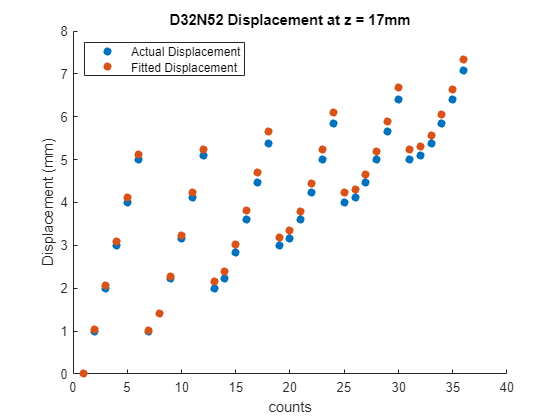


scatter(1:length(zi2), zi2, 'filled')
hold on;
scatter(1:length(testx), testx, 'filled')
title('D32N52 Displacement at z = 17mm')
xlabel('counts')
ylabel('Displacement (mm)')
legend('Actual Displacement', 'Fitted Displacement', Location='northwest')
hold off;

SSR = sum((zi2 - testx).^2)

SSR =        1.1914


SST = sum((zi2 - mean(testx)).^2)

SST =        102.05


R2 = 1 - SSR/SST

R2 =       0.98833


02/07/2024

Plot R^2 vs distance

Redo plots with more magnets (inbetween) at different distances (go to z=12mm).

Find threshold distance for different magnets.

Calculate mean distance between blue points and line.

Rotate sensor by 90degrees

Rough draft of poster + one page supporting document

Take measurement in gamma knife without micrometer stage (maybe with rotational stages + live fitting from server. 

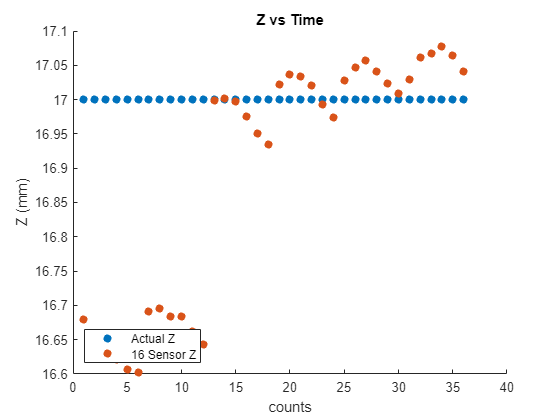

scatter(1:length(multiloc),loc(:,3), 'filled')
hold on;
scatter(1:length(multiloc), multiloc(:,3), 'filled')
title('Z vs Time')
xlabel('counts')
ylabel('Z (mm)')
%ylim([31,33])
legend('Actual Z','16 Sensor Z', Location='southwest')
hold off;

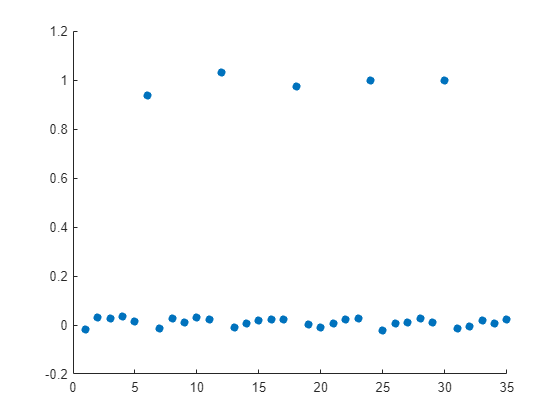

test = diff(multiloc(:,1));
scatter(1:length(test), test, 'filled')
hold on;
hold off;

multidisp = multiloc + [2 2 -17]

multidisp =       -1.5576       -2.058     -0.32007
      -1.5766      -1.0298     -0.34161
      -1.5468    0.0025395     -0.36351
      -1.5197       1.0245     -0.37831
       -1.483       2.0467     -0.39367
      -1.4681       3.0613     -0.39752
     -0.53254      -2.0916     -0.30826
     -0.54737      -1.0742      -0.3039
     -0.52167    -0.024699     -0.31587
     -0.51011       1.0077      -0.3161


multidisp = sqrt(sum(multidisp.^2, 2))

multidisp =        2.6008
       1.9138
       1.5889
       1.8714
        2.558
       3.4183
       2.1802
       1.2433
      0.61035
       1.1729



disp = [4.98 5.08 5.35 5.78 6.34 7.01 5.08 5.18 5.45 5.9 6.46 7.12 5.37 5.47 5.74 6.13 6.66 7.3 5.81 5.91 6.15 6.55 7.05 7.67 6.41 6.47 6.70 7.05 7.55 8.11 7.06 7.13 7.34 7.67 8.1 8.65]'

disp =          4.98
         5.08
         5.35
         5.78
         6.34
         7.01
         5.08
         5.18
         5.45
          5.9


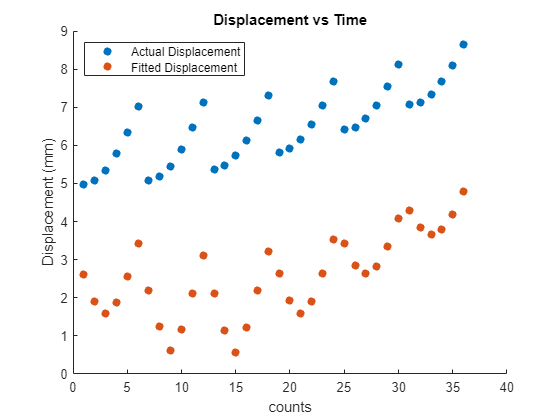


scatter(1:length(disp), disp, 'filled')
hold on;
scatter(1:length(multidisp), multidisp, 'filled')
title('Displacement vs Time')
xlabel('counts')
ylabel('Displacement (mm)')
legend('Actual Displacement', 'Fitted Displacement', Location='northwest')
hold off;

function a = anglecost(v, loc, B_data, B_t, datasize, sensor)
X1 = sensor - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], datasize, 1);
a = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function [c, ceq] = con(v)
c = [];
ceq = sqrt(sum([v(1) v(2) v(3)].^2, 2)) - 1;
end

function b = loccost(x, angle, B_data, B_t, sensor)
X1 = sensor - [x(1) x(2) x(3)];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem(angle, 1, 1);
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function b = bothcost(v, B_data, B_t)
H_0 = repelem([v(1) v(2) v(3)], 1, 1);
X1 = [-v(4) -v(5) -v(6)];
R1 = sqrt(sum(X1.^2, 2));
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function s = senloc(x, loc, B_data, B_t, datasize)
X1 = [x(1) x(2) x(3)] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([0 0 -1], datasize, 1);
s = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function m = multicost(v, sen1, sen2, sen3, sen4, B_t)
loc = [v(4) v(5) v(6)];
X1 = [0 0 0] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], 1, 1);
X2 = [-25 0 0] - loc;
R2 = sqrt(sum(X2.^2, 2));
X3 = [0 25 0] - loc;
R3 = sqrt(sum(X3.^2, 2));
X4 = [-25 25 0] - loc;
R4 = sqrt(sum(X4.^2, 2));
m = sum(sum((sen1 - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2) + sum((sen2 - B_t*(3*dot(H_0, X2, 2).*X2./R2.^5-H_0./R2.^3)).^2) ...
    + sum((sen3 - B_t*(3*dot(H_0, X3, 2).*X3./R3.^5-H_0./R3.^3)).^2) + sum((sen4 - B_t*(3*dot(H_0, X4, 2).*X4./R4.^5-H_0./R4.^3)).^2));
end

function mm = mmcost(v, B_t, sensor_grid, sensor_data, s1, s2)
    H_0 = repelem([v(1) v(2) v(3)], 1, 1);
    loc = [v(4) v(5) v(6)];
    s = sensor_data;
    mm = 0;
    for i = s1:s2
        X = sensor_grid(i, :) - loc;
        R = sqrt(sum(X.^2, 2));
        mm = mm + sum((s(3*i-2:3*i) - B_t * (3 * dot(H_0, X, 2) .* X ./ R.^5 - H_0 ./ R.^3)).^2);
    end
end